clc;
clear;
inputFolder = 'test/todos';

ads = audioDatastore(inputFolder, 'IncludeSubfolders', false, 'FileExtensions', '.wav');

classes = [];
fileNames = {};

% Leer los archivos y asignar las clases
while hasdata(ads)
    [audioData, dsInfo] = read(ads);

    % Extraer clase del nombre del archivo
    [~, fileName, ~] = fileparts(dsInfo.FileName);
    splitName = split(fileName, '_');
    classLabel = str2double(splitName{1});
    
    % Guardar la clase y el nombre
    classes = [classes; classLabel];
    fileNames{end+1} = dsInfo.FileName;
    
    fprintf('Archivo: %s, Clase: %d, Duración: %.2f segundos\n', ...
        fileName, classLabel, numel(audioData) / dsInfo.SampleRate);
end

Archivo: 10_Diego_Test, Clase: 10, Duración: 1.00 segundos
Archivo: 10_Miguel_Test, Clase: 10, Duración: 1.00 segundos
Archivo: 10_Nancy_test, Clase: 10, Duración: 1.00 segundos
Archivo: 10_Valeria_Test, Clase: 10, Duración: 1.00 segundos
Archivo: 1_Diego_Test, Clase: 1, Duración: 1.00 segundos
Archivo: 1_Miguel_Test, Clase: 1, Duración: 1.00 segundos
Archivo: 1_Nancy_test, Clase: 1, Duración: 1.00 segundos
Archivo: 1_Valeria_Test, Clase: 1, Duración: 1.00 segundos
Archivo: 2_Diego_Test, Clase: 2, Duración: 1.00 segundos
Archivo: 2_Miguel_Test, Clase: 2, Duración: 1.00 segundos
Archivo: 2_Nancy_test, Clase: 2, Duración: 1.00 segundos
Archivo: 2_Valeria_Test, Clase: 2, Duración: 1.00 segundos
Archivo: 3_Diego_Test, Clase: 3, Duración: 1.00 segundos
Archivo: 3_Miguel_Test, Clase: 3, Duración: 1.00 segundos
Archivo: 3_Nancy_test, Clase: 3, Duración: 1.00 segundos
Archivo: 3_Valeria_Test, Clase: 3, Duración: 1.00 segundos
Archivo: 4_Diego_Test, Clase: 4, Duración: 1.00 segundos
Archivo: 4_

fprintf('Se procesaron %d archivos.\n', numel(fileNames));

Se procesaron 40 archivos.


as

fs = dsInfo.SampleRate;
windowLength = round(0.03 * fs); % Ventana de 30 ms
overlapLength = round(0.025 * fs); % Solapamiento de 25 ms

afe = audioFeatureExtractor( ...
    SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"), ...
    OverlapLength=overlapLength, ...
    zerocrossrate=true, ...
    shortTimeEnergy=true, ...
    pitch=true, ...
    mfcc=true);

featureMap = info(afe);

features = [];
labels = [];
energyThreshold = 0.005; % Umbral para energía
zcrThreshold = 0.2; % Umbral para tasa de cruces por cero

% Reiniciar el puntero del datastore
reset(ads);

% Extraer características y filtrar
while hasdata(ads)
    [audioData, dsInfo] = read(ads);

    % Extraer características del audio
    thisFeature = extract(afe, audioData);
    isSpeech = thisFeature(:, featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:, featureMap.zerocrossrate) < zcrThreshold;

    % Identificar regiones de voz
    voicedSpeech = isSpeech & isVoiced;

    % Filtrar características no deseadas
    thisFeature(~voicedSpeech, :) = [];
    thisFeature(:, [featureMap.zerocrossrate, featureMap.shortTimeEnergy]) = [];

    % Obtener la etiqueta correspondiente al archivo
    [~, fileName, ~] = fileparts(dsInfo.FileName);
    splitName = split(fileName, '_');
    classLabel = str2double(splitName{1});

    % Asignar etiquetas
    label = repelem(classLabel, size(thisFeature, 1))';
    
    % Guardar características y etiquetas
    features = [features; thisFeature];
    labels = [labels; label];
end

M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

fprintf('Extraccion terminada\n');

Extraccion terminada


load('knnModel.mat', 'trainedClassifier');

predictedLabels = predict(trainedClassifier, features);

% Evaluar la precisión comparando las etiquetas predichas con las etiquetas reales
accuracy = sum(predictedLabels == labels) / length(labels);

fprintf('La precisión de la clasificación en el conjunto de prueba es: %.2f%%\n', accuracy * 100);

La precisión de la clasificación en el conjunto de prueba es: 35.95%


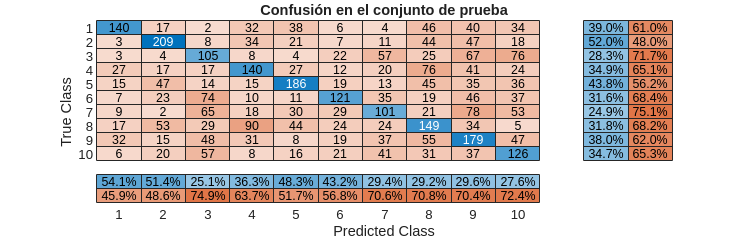


% Opcional: Mostrar una matriz de confusión
figure('Units', "normalized", 'Position', [0.4, 0.4, 0.4, 0.4]);
confusionchart(labels, predictedLabels, 'Title', 'Confusión en el conjunto de prueba', ...
    'ColumnSummary', "column-normalized", 'RowSummary', "row-normalized");